## Plot diff_m_throughput based on  `Gamma NF`

clc
clear all
close all

theta_diff_m_throughput = []; 

for i = 1:3
    num_bit = 1;
    UAV_N = 3;
    num_iteration = 1e03;
    freq = 2e09; % GHz
    R = 3;
    
    gamma_NF_db = [12:30];
    gamma_NF = 10.^(gamma_NF_db/10);
    gamma_th = 4.5e-08;
    
    m_AU = i;
    omega_AU = 1;
    m_UB = i;
    omega_UB = 2;
    
    pl_exponent = 2; % for LOS
    
    GU_A_coor = [-600, 0, 0];
    GU_B_coor = [+600, 0, 0];
    UAV_H = 100; % meter
    
    coor = [-500:5:500];
    UAVs_coor = reshape(coor(randperm(size(coor,2), UAV_N*2)), [UAV_N, 2]);
    
    UAVs_coor = cat(2, UAVs_coor, repmat(UAV_H, [UAV_N, 1]));
    Troughput_prob = zeros(1,length(gamma_NF_db));
    
    parfor gamma_NF_index = 1:length(gamma_NF_db)
        Troughput_sum = 0;
%         x_num = 0;
        for iter = 1:num_iteration
            fading_AU = repmat(random('nakagami', m_AU, omega_AU, [1, num_bit]), 1, UAV_N);
            fading_UB = repmat(random('nakagami', m_UB, omega_UB, [1, num_bit]), 1, UAV_N);
            
            dist_AU = vecnorm((repmat(GU_A_coor, UAV_N,1) - UAVs_coor)');
            dist_UB = vecnorm((repmat(GU_B_coor, UAV_N,1) - UAVs_coor)');
            path_loss_AU = ((3e08/(4*pi*freq))^2) * (dist_AU.^(-pl_exponent));
            path_loss_UB = ((3e08/(4*pi*freq))^2) * (dist_UB.^(-pl_exponent));
            
            h_AU = fading_AU .* sqrt(path_loss_AU);
            h_UB = fading_UB .* sqrt(path_loss_UB);
            
            gamma_AU = (abs(h_AU).^2)*gamma_NF(gamma_NF_index);
            gamma_UB = (abs(h_UB).^2)*gamma_NF(gamma_NF_index);
            
%             c = gamma_AU > gamma_th;
            c = 1;

            theta_i = gamma_UB .* c;
            % Selection
            [argvalue, argmax] = max(theta_i);
            
            selected_uav = argmax;
            selected_uav_coor = UAVs_coor(selected_uav, :);
            
            gamma_hat_AU = omega_AU * path_loss_AU * gamma_NF(gamma_NF_index)/m_AU;
            gamma_hat_UB = omega_UB * path_loss_UB * gamma_NF(gamma_NF_index)/m_UB;
            
            selected_uav_theta = argvalue;
%             if selected_uav_theta <= gamma_th
%                 x_num = x_num + 1;
%                 continue
%             end
            theta_CDF_each = theta_CDF(gamma_th, gamma_hat_AU ,gamma_hat_UB, m_AU, m_UB);
            theta_CDF_prod = prod(theta_CDF_each);
            Troughput_sum = Troughput_sum + (1 - theta_CDF_prod) * (R/2);
        end
        Troughput_prob(gamma_NF_index) = Troughput_sum / (num_iteration);
    end
    disp(i)
    theta_diff_m_throughput = [theta_diff_m_throughput ; Troughput_prob];
end

     1

     2

     3



save('result/theta_diff_m_throughput', 'theta_diff_m_throughput');

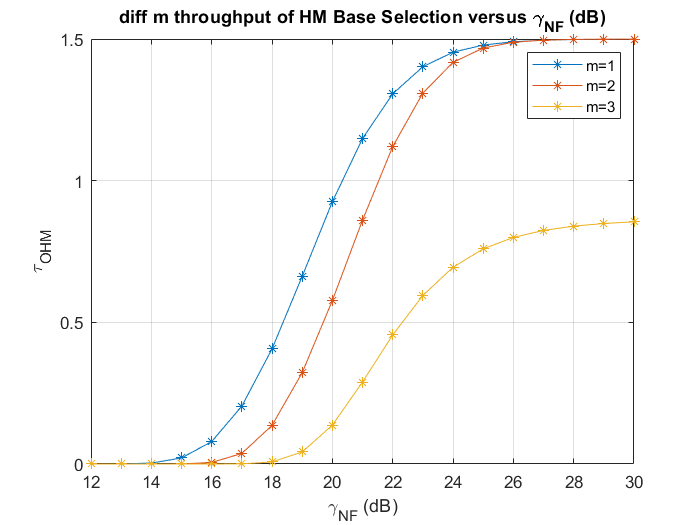

figure()
plot(gamma_NF_db, theta_diff_m_throughput(1,:),'-*')
hold on
plot(gamma_NF_db, theta_diff_m_throughput(2,:),'-*')
hold on
plot(gamma_NF_db, theta_diff_m_throughput(3,:),'-*')

xlabel('\gamma_{NF} (dB)'); ylabel('\tau_{OHM}'); title('diff m throughput of HM Base Selection versus \gamma_{NF} (dB)')
h = legend('m=1', 'm=2', 'm=3');
set(h,'Interpreter','none')
grid on, hold on
% ylim([0 1.5])
xticks(12:2:30)
yticks(0:0.5:1.5)